# Presentación Final (Cinemática Diferencial de Piernas) Ejercicio 1

## Daniel Castillo López A01737357

- **Obtener **la matriz de  transformación **homogénea global T, empleando variables simbólicas** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base). Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

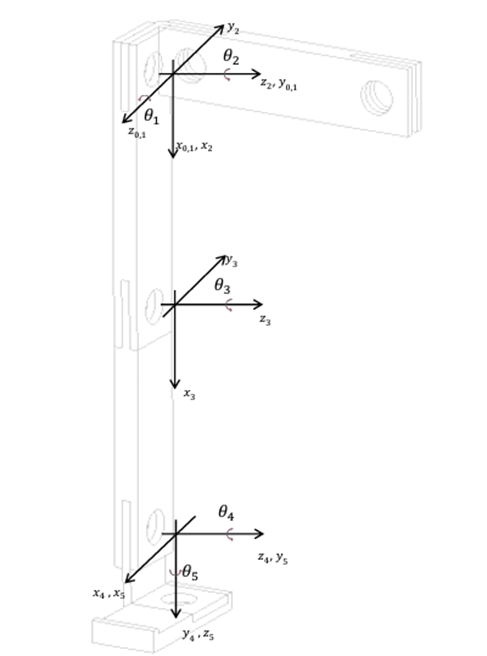

- **Desarrollar** el modelo de **cinemática diferencial simbólica** para cada uno de los sistemas descritos anteriormente y obtener los vectores de la **velocidad angular y velocidad lineal** aplicando variables simbólicas para su análisis en cada caso.

- **Implementar** el código requerido para generar el cálculo de las matrices **homogéneas simbólicas (H1, H2, H3, etc.),** la matriz de **transformación simbólica (T)** y los vectores de **velocidades simbólicas (v, w)** de cada sistema.

%Limpieza de pantalla
clear all
close all
clc

Aquí se definen las matrices de transformación homogénea que representan los movimientos y orientaciones relativas entre diferentes marcos de referencia (tramas).H0 es la matriz identidad, correspondiente a la trama global. Luego, se aplican transformaciones sucesivas que incluyen rotaciones y traslaciones, simulando el comportamiento de un brazo robótico o sistema articulado. Las transformaciones están en el espacio 3D, y son acumulativas.

%Calculamos las matrices de transformación homogénea
H0=SE3;                             %Matriz identidad
%H0=SE3(roty(pi), [0 0 0]); 
H1=SE3(rotx(-90*pi/180), [0 0 0])*SE3(rotz(90*pi/180), [0 0 0]);
%H2=SE3(rotx(pi/2), [0 0 0]);
H2=SE3(rotx(-90*pi/180), [0 0 0]);
H3=SE3([3 0 0]);
H4=SE3(rotz(-90*pi/180), [3 0 0]);
H5=SE3(rotx(90*pi/180), [0 0 0])

 

H5 = 
         1         0         0         0
         0         0        -1         0
         0         1         0         0
         0         0         0         1


n este bloque se calculan las transformaciones compuestas entre tramas consecutivas. Estas operaciones de multiplicación de matrices permiten determinar la posición y orientación final de cada trama en relación con la trama base (H0). Este enfoque es común en cinemática directa para cadenas cinemáticas, como robots manipuladores.

H0_1= H0*H1;
H1_2= H0_1*H2;
H2_3= H1_2*H3; %Matriz de transformación homogenea global de 3 a 0 
H3_4= H2_3*H4;
H4_5= H3_4*H5

 

H4_5 = 
         0        -1         0         0
         1         0         0         0
         0         0         1        -6
         0         0         0         1


Se extraen las posiciones (vectores de traslación) de cada una de las matrices de transformación homogénea utilizando la función transl. Esto permite obtener las coordenadas espaciales (x, y, z) de cada punto asociado a las tramas, que serán utilizados posteriormente para trazar la trayectoria.


% Construir los puntos de la trayectoria a partir de los vectores de posición de cada transformación
P0 = transl(H0);     % [x y z]
P1 = transl(H0_1);
P2 = transl(H1_2);
P3 = transl(H2_3);
P4 = transl(H3_4);
P5 = transl(H4_5);


En este bloque se construyen los vectores x, y y z que almacenan las coordenadas de los puntos clave a lo largo de la trayectoria del sistema. Estas coordenadas se utilizarán para graficar la trayectoria tridimensional del sistema articulado.

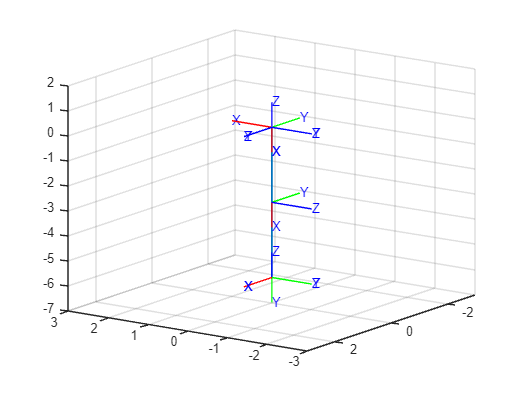

% Unir todos los puntos en vectores x, y, z para graficar el trazo
x = [P0(1) P1(1) P2(1) P3(1) P4(1) P5(1)];
y = [P0(2) P1(2) P2(2) P3(2) P4(2) P5(2)];
z = [P0(3) P1(3) P2(3) P3(3) P4(3) P5(3)];


plot3(x, y, z, 'LineWidth', 1.5);
axis([-3 3 -3 3 -7 2]); % Limites de los ejes X, Y, Z
grid on;
view(-145, 17);         % Ajusta la vista: azimut = -133°, elevación = 10°

hold on;
%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-4 4 -2 6 -7 1])
% 
% %Realizamos una animación para la siguiente trama
 snapnow;
  tranimate(H0, H0_1,'rgb','axis', [-4 4 -2 6 -7 1])
% %Realizamos una animación para la siguiente trama
snapnow;
 tranimate(H0_1, H1_2,'rgb','axis', [-4 4 -2 6 -7 1])
% % %Realizamos una animación para la siguiente trama
 snapnow;           
  tranimate(H1_2, H2_3,'rgb','axis', [-4 4 -2 6 -7 1])
snapnow;  
   tranimate(H2_3, H3_4,'rgb','axis', [-4 4 -2 6 -7 1])
    snapnow;           
  tranimate(H3_4, H4_5,'rgb','axis', [-4 4 -2 6 -7 1])


  disp(H4_5)

    0        -1         0         0
    1         0         0         0
    0         0         1        -6
    0         0         0         1
